## **Limpiar variables**

 
clear

## Valores iniciales

**Posición del robot**

x = 0;
y = 0;
z = 0;
p_robot = [x; y; z];

**Orientación del robot**

phi = 0;    %Rotación en el eje X
theta = 0;  %Rotación en el eje Y
psi = 0;    %Rotación en el eje Z
ori_robot = deg2rad([phi; theta; psi]);
secuencia = "XYZ";

**Matriz de transformación homogenea inicial**

R_inicial = euler2rotMat(ori_robot,secuencia);

R =      1     0     0
     0     1     0
     0     0     1


R =      1     0     0
     0     1     0
     0     0     1


R =      1     0     0
     0     1     0
     0     0     1


A0 = [R_inicial  p_robot
      zeros(1,3) 1];

**Crear estructura del robot en base a la tabla DH y los valores iniciales**

dh = readtable('datos\tabla_DH\robot10.csv');
robot = crear_robot(dh,A0);

**Trayectoria cartesiana del robot**

p = readtable("datos\trayectorias\cargar_trayectoria_1.csv");
n = length(p.x);
%+ R_puntos = zeros(3,3,n);
% for i = 1:n
%     euler_puntos = deg2rad([p.phi(i);p.theta(i);p.psi(i)]);
%     R_puntos(:,:,i) = euler2rotMat(euler_puntos,secuencia);
% end
pos_puntos = [p.x';p.y';p.z'];
% z_puntos = R_puntos(:,3,:);
 

## **Cinemática inversa de los puntos**

Se basa en el descenso del gradiente o jacobiano, donde a través de varias iteraciones y a una velocidad $\alpha$, se obtiene un valor objetivo reduciendo el error.

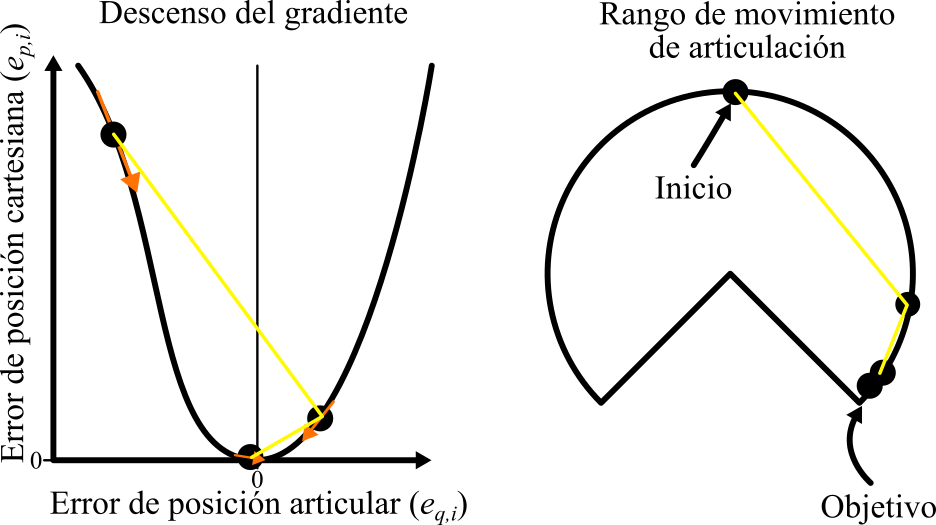

En caso de tener límites, a veces existen mínimos globales donde el descenso del gradiente no nos permitirá reducir más el error. Para solucionarlo, se usan varios candidatos que se distribuyen uniformemente en todo el rango de las articulacuiones y así al menos uno de ellos llegará al error objetivo.

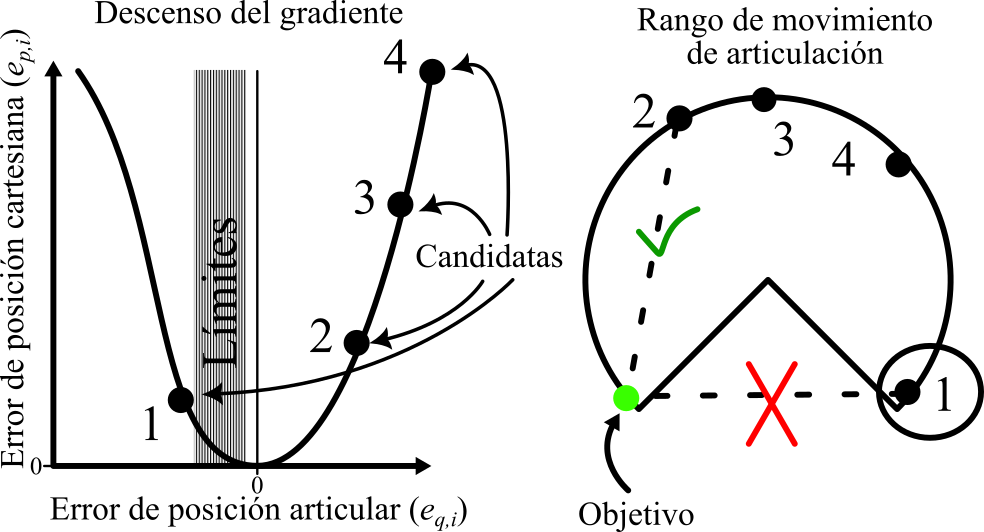

tol = 1e-6; % error máximo tolerado
max_iter = 100; % iteraciones del descenso del gradiente
alpha = 1.0;    % factor de corrección del descenso del gradiente
numSamples = 9; % Esto sirve para buscar diferentes puntos en caso de llegar a un mínimo local
q_sol = zeros(robot.NGDL,n);
p_sol = zeros(size(pos_puntos));
for i = 1:n
    [q_sol(:,i),p_sol(:,i)] = cinematica_inv(robot, pos_puntos(:,i), tol, max_iter, alpha, numSamples);
end

Ningún candidato alcanzó la tolerancia; se elige el candidato con error = 9.028863e-01
Ningún candidato alcanzó la tolerancia; se elige el candidato con error = 2.190718e+00


## **Trayectoria de punto articular a punto articular**

% Calcular la diferencia entre la configuración final y la inicial para cada junta
delta_q = abs(q_sol(:,2) - q_sol(:,1));
% Usar el valor más alto de los tiempos mínimos requeridos para cada junta,
% de forma que siempre sea un perfil triangular.
t_final = max(2 * delta_q ./ robot.dqMax);
% Muestras para graficar trayectoria
numSamples = 201;

[q, dq, ddq, t, pp] = trapveltraj(q_sol, numSamples, ...
                                            'Acceleration', robot.ddqMax, ...
                                            'EndTime', t_final);

## Cinemática directa

[posicion, vel_linear, acel_linear, orientacion, vel_angular, acel_angular] = cinematica_dir(robot,q,dq,ddq,t,secuencia);

phi = 0.4269

theta = -1.1201

psi = -0.3970

euler =     0.4269
   -1.1201
   -0.3970


phi = 0.4275

theta = -1.1201

psi = -0.3965

euler =     0.4275
   -1.1201
   -0.3965


phi = 0.4294

theta = -1.1199

psi = -0.3951

euler =     0.4294
   -1.1199
   -0.3951


phi = 0.4325

theta = -1.1195

psi = -0.3926

euler =     0.4325
   -1.1195
   -0.3926


phi = 0.4368

theta = -1.1190

psi = -0.3892

euler =     0.4368
   -1.1190
   -0.3892


phi = 0.4423

theta = -1.1184

psi = -0.3848

euler =     0.4423
   -1.1184
   -0.3848


phi = 0.4490

theta = -1.1178

psi = -0.3793

euler =     0.4490
   -1.1178
   -0.3793


phi = 0.4567

theta = -1.1170

psi = -0.3728

euler =     0.4567
   -1.1170
   -0.3728


phi = 0.4655

theta = -1.1163

psi = -0.3652

euler =     0.4655
   -1.1163
   -0.3652


phi = 0.4754

theta = -1.1155

psi = -0.3565

euler =     0.4754
   -1.1155
   -0.3565


phi = 0.4863

theta = -1.1146

psi = -0.3468

euler =     0.4863
   -1.1146
   -0.3468


phi = 0.4983

theta = -1.1136

psi = -0.3360

euler =     0.4983
   -1.1136
   -0.3360


phi = 0.5114

theta = -1.1125

psi = -0.3242

euler =     0.5114
   -1.1125
   -0.3242


phi = 0.5254

theta = -1.1113

psi = -0.3114

euler =     0.5254
   -1.1113
   -0.3114


phi = 0.5405

theta = -1.1099

psi = -0.2976

euler =     0.5405
   -1.1099
   -0.2976


phi = 0.5565

theta = -1.1084

psi = -0.2828

euler =     0.5565
   -1.1084
   -0.2828


phi = 0.5735

theta = -1.1067

psi = -0.2671

euler =     0.5735
   -1.1067
   -0.2671


phi = 0.5914

theta = -1.1047

psi = -0.2505

euler =     0.5914
   -1.1047
   -0.2505


phi = 0.6103

theta = -1.1026

psi = -0.2330

euler =     0.6103
   -1.1026
   -0.2330


phi = 0.6300

theta = -1.1002

psi = -0.2147

euler =     0.6300
   -1.1002
   -0.2147


phi = 0.6505

theta = -1.0974

psi = -0.1955

euler =     0.6505
   -1.0974
   -0.1955


phi = 0.6719

theta = -1.0944

psi = -0.1757

euler =     0.6719
   -1.0944
   -0.1757


phi = 0.6939

theta = -1.0911

psi = -0.1551

euler =     0.6939
   -1.0911
   -0.1551


phi = 0.7167

theta = -1.0874

psi = -0.1339

euler =     0.7167
   -1.0874
   -0.1339


phi = 0.7400

theta = -1.0833

psi = -0.1121

euler =     0.7400
   -1.0833
   -0.1121


phi = 0.7640

theta = -1.0787

psi = -0.0897

euler =     0.7640
   -1.0787
   -0.0897


phi = 0.7885

theta = -1.0738

psi = -0.0670

euler =     0.7885
   -1.0738
   -0.0670


phi = 0.8134

theta = -1.0683

psi = -0.0438

euler =     0.8134
   -1.0683
   -0.0438


phi = 0.8387

theta = -1.0624

psi = -0.0203

euler =     0.8387
   -1.0624
   -0.0203


phi = 0.8643

theta = -1.0560

psi = 0.0034

euler =     0.8643
   -1.0560
    0.0034


phi = 0.8901

theta = -1.0491

psi = 0.0273

euler =     0.8901
   -1.0491
    0.0273


phi = 0.9162

theta = -1.0415

psi = 0.0512

euler =     0.9162
   -1.0415
    0.0512


phi = 0.9423

theta = -1.0335

psi = 0.0752

euler =     0.9423
   -1.0335
    0.0752


phi = 0.9685

theta = -1.0248

psi = 0.0991

euler =     0.9685
   -1.0248
    0.0991


phi = 0.9946

theta = -1.0155

psi = 0.1229

euler =     0.9946
   -1.0155
    0.1229


phi = 1.0207

theta = -1.0057

psi = 0.1465

euler =     1.0207
   -1.0057
    0.1465


phi = 1.0466

theta = -0.9952

psi = 0.1699

euler =     1.0466
   -0.9952
    0.1699


phi = 1.0723

theta = -0.9840

psi = 0.1929

euler =     1.0723
   -0.9840
    0.1929


phi = 1.0978

theta = -0.9722

psi = 0.2155

euler =     1.0978
   -0.9722
    0.2155


phi = 1.1229

theta = -0.9598

psi = 0.2377

euler =     1.1229
   -0.9598
    0.2377


phi = 1.1478

theta = -0.9467

psi = 0.2595

euler =     1.1478
   -0.9467
    0.2595


phi = 1.1723

theta = -0.9330

psi = 0.2807

euler =     1.1723
   -0.9330
    0.2807


phi = 1.1964

theta = -0.9186

psi = 0.3013

euler =     1.1964
   -0.9186
    0.3013


phi = 1.2201

theta = -0.9035

psi = 0.3214

euler =     1.2201
   -0.9035
    0.3214


phi = 1.2434

theta = -0.8878

psi = 0.3408

euler =     1.2434
   -0.8878
    0.3408


phi = 1.2662

theta = -0.8715

psi = 0.3596

euler =     1.2662
   -0.8715
    0.3596


phi = 1.2885

theta = -0.8545

psi = 0.3778

euler =     1.2885
   -0.8545
    0.3778


phi = 1.3104

theta = -0.8368

psi = 0.3952

euler =     1.3104
   -0.8368
    0.3952


phi = 1.3319

theta = -0.8185

psi = 0.4119

euler =     1.3319
   -0.8185
    0.4119


phi = 1.3529

theta = -0.7996

psi = 0.4280

euler =     1.3529
   -0.7996
    0.4280


phi = 1.3734

theta = -0.7800

psi = 0.4433

euler = 3×1
    1.3734
   -0.7800
    0.4433


phi = 1.3932

theta = -0.7601

psi = 0.4577

euler = 3×1
    1.3932
   -0.7601
    0.4577


phi = 1.4123

theta = -0.7399

psi = 0.4711

euler = 3×1
    1.4123
   -0.7399
    0.4711


phi = 1.4306

theta = -0.7196

psi = 0.4836

euler = 3×1
    1.4306
   -0.7196
    0.4836


phi = 1.4482

theta = -0.6991

psi = 0.4952

euler = 3×1
    1.4482
   -0.6991
    0.4952


phi = 1.4652

theta = -0.6784

psi = 0.5059

euler = 3×1
    1.4652
   -0.6784
    0.5059


phi = 1.4816

theta = -0.6576

psi = 0.5159

euler = 3×1
    1.4816
   -0.6576
    0.5159


phi = 1.4975

theta = -0.6367

psi = 0.5251

euler = 3×1
    1.4975
   -0.6367
    0.5251


phi = 1.5129

theta = -0.6157

psi = 0.5336

euler = 3×1
    1.5129
   -0.6157
    0.5336


phi = 1.5279

theta = -0.5946

psi = 0.5414

euler = 3×1
    1.5279
   -0.5946
    0.5414


phi = 1.5424

theta = -0.5734

psi = 0.5486

euler = 3×1
    1.5424
   -0.5734
    0.5486


phi = 1.5566

theta = -0.5521

psi = 0.5551

euler = 3×1
    1.5566
   -0.5521
    0.5551


phi = 1.5704

theta = -0.5308

psi = 0.5610

euler = 3×1
    1.5704
   -0.5308
    0.5610


phi = -1.5577

theta = -0.5094

psi = 0.5663

euler = 3×1
   -1.5577
   -0.5094
    0.5663


phi = -1.5445

theta = -0.4880

psi = 0.5711

euler = 3×1
   -1.5445
   -0.4880
    0.5711


phi = -1.5316

theta = -0.4666

psi = 0.5754

euler = 3×1
   -1.5316
   -0.4666
    0.5754


phi = -1.5189

theta = -0.4451

psi = 0.5791

euler = 3×1
   -1.5189
   -0.4451
    0.5791


phi = -1.5064

theta = -0.4236

psi = 0.5823

euler = 3×1
   -1.5064
   -0.4236
    0.5823


phi = -1.4942

theta = -0.4021

psi = 0.5851

euler = 3×1
   -1.4942
   -0.4021
    0.5851


phi = -1.4821

theta = -0.3806

psi = 0.5873

euler = 3×1
   -1.4821
   -0.3806
    0.5873


phi = -1.4701

theta = -0.3591

psi = 0.5891

euler = 3×1
   -1.4701
   -0.3591
    0.5891


phi = -1.4583

theta = -0.3376

psi = 0.5905

euler = 3×1
   -1.4583
   -0.3376
    0.5905


phi = -1.4465

theta = -0.3161

psi = 0.5914

euler = 3×1
   -1.4465
   -0.3161
    0.5914


phi = -1.4349

theta = -0.2947

psi = 0.5919

euler = 3×1
   -1.4349
   -0.2947
    0.5919


phi = -1.4234

theta = -0.2733

psi = 0.5920

euler = 3×1
   -1.4234
   -0.2733
    0.5920


phi = -1.4119

theta = -0.2519

psi = 0.5917

euler = 3×1
   -1.4119
   -0.2519
    0.5917


phi = -1.4004

theta = -0.2306

psi = 0.5909

euler = 3×1
   -1.4004
   -0.2306
    0.5909


phi = -1.3890

theta = -0.2094

psi = 0.5898

euler = 3×1
   -1.3890
   -0.2094
    0.5898


phi = -1.3776

theta = -0.1882

psi = 0.5882

euler = 3×1
   -1.3776
   -0.1882
    0.5882


phi = -1.3662

theta = -0.1670

psi = 0.5863

euler = 3×1
   -1.3662
   -0.1670
    0.5863


phi = -1.3548

theta = -0.1459

psi = 0.5839

euler = 3×1
   -1.3548
   -0.1459
    0.5839


phi = -1.3433

theta = -0.1250

psi = 0.5812

euler = 3×1
   -1.3433
   -0.1250
    0.5812


phi = -1.3318

theta = -0.1041

psi = 0.5781

euler = 3×1
   -1.3318
   -0.1041
    0.5781


phi = -1.3202

theta = -0.0832

psi = 0.5745

euler = 3×1
   -1.3202
   -0.0832
    0.5745


phi = -1.3085

theta = -0.0625

psi = 0.5706

euler = 3×1
   -1.3085
   -0.0625
    0.5706


phi = -1.2968

theta = -0.0419

psi = 0.5663

euler = 3×1
   -1.2968
   -0.0419
    0.5663


phi = -1.2850

theta = -0.0214

psi = 0.5616

euler = 3×1
   -1.2850
   -0.0214
    0.5616


phi = -1.2730

theta = -0.0010

psi = 0.5565

euler = 3×1
   -1.2730
   -0.0010
    0.5565


phi = -1.2609

theta = 0.0192

psi = 0.5510

euler = 3×1
   -1.2609
    0.0192
    0.5510


phi = -1.2487

theta = 0.0393

psi = 0.5451

euler = 3×1
   -1.2487
    0.0393
    0.5451


phi = -1.2363

theta = 0.0593

psi = 0.5388

euler = 3×1
   -1.2363
    0.0593
    0.5388


phi = -1.2238

theta = 0.0791

psi = 0.5321

euler = 3×1
   -1.2238
    0.0791
    0.5321


phi = -1.2110

theta = 0.0988

psi = 0.5250

euler = 3×1
   -1.2110
    0.0988
    0.5250


phi = -1.1981

theta = 0.1183

psi = 0.5175

euler = 3×1
   -1.1981
    0.1183
    0.5175


phi = -1.1850

theta = 0.1376

psi = 0.5095

euler = 3×1
   -1.1850
    0.1376
    0.5095


phi = -1.1716

theta = 0.1567

psi = 0.5011

euler = 3×1
   -1.1716
    0.1567
    0.5011


phi = -1.1580

theta = 0.1757

psi = 0.4923

euler = 3×1
   -1.1580
    0.1757
    0.4923


phi = -1.1442

theta = 0.1944

psi = 0.4830

euler = 3×1
   -1.1442
    0.1944
    0.4830


phi = -1.1301

theta = 0.2129

psi = 0.4733

euler = 3×1
   -1.1301
    0.2129
    0.4733


phi = -1.1158

theta = 0.2312

psi = 0.4631

euler = 3×1
   -1.1158
    0.2312
    0.4631


phi = -1.1011

theta = 0.2493

psi = 0.4524

euler = 3×1
   -1.1011
    0.2493
    0.4524


phi = -1.0862

theta = 0.2671

psi = 0.4413

euler = 3×1
   -1.0862
    0.2671
    0.4413


phi = -1.0709

theta = 0.2846

psi = 0.4297

euler = 3×1
   -1.0709
    0.2846
    0.4297


phi = -1.0554

theta = 0.3019

psi = 0.4176

euler = 3×1
   -1.0554
    0.3019
    0.4176


phi = -1.0395

theta = 0.3189

psi = 0.4050

euler = 3×1
   -1.0395
    0.3189
    0.4050


phi = -1.0232

theta = 0.3357

psi = 0.3920

euler = 3×1
   -1.0232
    0.3357
    0.3920


phi = -1.0066

theta = 0.3521

psi = 0.3784

euler = 3×1
   -1.0066
    0.3521
    0.3784


phi = -0.9896

theta = 0.3681

psi = 0.3643

euler = 3×1
   -0.9896
    0.3681
    0.3643


phi = -0.9723

theta = 0.3839

psi = 0.3496

euler = 3×1
   -0.9723
    0.3839
    0.3496


phi = -0.9546

theta = 0.3993

psi = 0.3345

euler = 3×1
   -0.9546
    0.3993
    0.3345


phi = -0.9365

theta = 0.4143

psi = 0.3188

euler = 3×1
   -0.9365
    0.4143
    0.3188


phi = -0.9179

theta = 0.4290

psi = 0.3026

euler = 3×1
   -0.9179
    0.4290
    0.3026


phi = -0.8990

theta = 0.4432

psi = 0.2858

euler = 3×1
   -0.8990
    0.4432
    0.2858


phi = -0.8797

theta = 0.4571

psi = 0.2685

euler = 3×1
   -0.8797
    0.4571
    0.2685


phi = -0.8599

theta = 0.4705

psi = 0.2506

euler = 3×1
   -0.8599
    0.4705
    0.2506


phi = -0.8397

theta = 0.4835

psi = 0.2322

euler = 3×1
   -0.8397
    0.4835
    0.2322


phi = -0.8191

theta = 0.4960

psi = 0.2132

euler = 3×1
   -0.8191
    0.4960
    0.2132


phi = -0.7981

theta = 0.5080

psi = 0.1937

euler = 3×1
   -0.7981
    0.5080
    0.1937


phi = -0.7767

theta = 0.5196

psi = 0.1737

euler = 3×1
   -0.7767
    0.5196
    0.1737


phi = -0.7549

theta = 0.5306

psi = 0.1531

euler = 3×1
   -0.7549
    0.5306
    0.1531


phi = -0.7326

theta = 0.5411

psi = 0.1321

euler = 3×1
   -0.7326
    0.5411
    0.1321


phi = -0.7100

theta = 0.5511

psi = 0.1104

euler = 3×1
   -0.7100
    0.5511
    0.1104


phi = -0.6870

theta = 0.5605

psi = 0.0883

euler = 3×1
   -0.6870
    0.5605
    0.0883


phi = -0.6636

theta = 0.5694

psi = 0.0658

euler = 3×1
   -0.6636
    0.5694
    0.0658


phi = -0.6398

theta = 0.5776

psi = 0.0427

euler = 3×1
   -0.6398
    0.5776
    0.0427


phi = -0.6158

theta = 0.5853

psi = 0.0192

euler = 3×1
   -0.6158
    0.5853
    0.0192


phi = -0.5914

theta = 0.5923

psi = -0.0047

euler = 3×1
   -0.5914
    0.5923
   -0.0047


phi = -0.5667

theta = 0.5987

psi = -0.0290

euler = 3×1
   -0.5667
    0.5987
   -0.0290


phi = -0.5418

theta = 0.6045

psi = -0.0537

euler = 3×1
   -0.5418
    0.6045
   -0.0537


phi = -0.5166

theta = 0.6096

psi = -0.0787

euler = 3×1
   -0.5166
    0.6096
   -0.0787


phi = -0.4912

theta = 0.6140

psi = -0.1041

euler = 3×1
   -0.4912
    0.6140
   -0.1041


phi = -0.4657

theta = 0.6178

psi = -0.1297

euler = 3×1
   -0.4657
    0.6178
   -0.1297


phi = -0.4401

theta = 0.6209

psi = -0.1555

euler = 3×1
   -0.4401
    0.6209
   -0.1555


phi = -0.4143

theta = 0.6233

psi = -0.1816

euler = 3×1
   -0.4143
    0.6233
   -0.1816


phi = -0.3885

theta = 0.6250

psi = -0.2078

euler = 3×1
   -0.3885
    0.6250
   -0.2078


phi = -0.3627

theta = 0.6260

psi = -0.2341

euler = 3×1
   -0.3627
    0.6260
   -0.2341


phi = -0.3370

theta = 0.6264

psi = -0.2605

euler = 3×1
   -0.3370
    0.6264
   -0.2605


phi = -0.3113

theta = 0.6260

psi = -0.2870

euler = 3×1
   -0.3113
    0.6260
   -0.2870


phi = -0.2857

theta = 0.6249

psi = -0.3134

euler = 3×1
   -0.2857
    0.6249
   -0.3134


phi = -0.2602

theta = 0.6232

psi = -0.3398

euler = 3×1
   -0.2602
    0.6232
   -0.3398


phi = -0.2349

theta = 0.6207

psi = -0.3662

euler = 3×1
   -0.2349
    0.6207
   -0.3662


phi = -0.2099

theta = 0.6176

psi = -0.3924

euler = 3×1
   -0.2099
    0.6176
   -0.3924


phi = -0.1852

theta = 0.6138

psi = -0.4184

euler = 3×1
   -0.1852
    0.6138
   -0.4184


phi = -0.1607

theta = 0.6094

psi = -0.4443

euler = 3×1
   -0.1607
    0.6094
   -0.4443


phi = -0.1366

theta = 0.6042

psi = -0.4699

euler = 3×1
   -0.1366
    0.6042
   -0.4699


phi = -0.1128

theta = 0.5985

psi = -0.4953

euler = 3×1
   -0.1128
    0.5985
   -0.4953


phi = -0.0894

theta = 0.5921

psi = -0.5205

euler = 3×1
   -0.0894
    0.5921
   -0.5205


phi = -0.0665

theta = 0.5851

psi = -0.5453

euler = 3×1
   -0.0665
    0.5851
   -0.5453


phi = -0.0440

theta = 0.5775

psi = -0.5698

euler = 3×1
   -0.0440
    0.5775
   -0.5698


phi = -0.0219

theta = 0.5694

psi = -0.5939

euler = 3×1
   -0.0219
    0.5694
   -0.5939


phi = -3.5240e-04

theta = 0.5606

psi = -0.6177

euler = 3×1
   -0.0004
    0.5606
   -0.6177


phi = 0.0205

theta = 0.5514

psi = -0.6409

euler = 3×1
    0.0205
    0.5514
   -0.6409


phi = 0.0405

theta = 0.5418

psi = -0.6633

euler = 3×1
    0.0405
    0.5418
   -0.6633


phi = 0.0596

theta = 0.5319

psi = -0.6848

euler = 3×1
    0.0596
    0.5319
   -0.6848


phi = 0.0777

theta = 0.5217

psi = -0.7055

euler = 3×1
    0.0777
    0.5217
   -0.7055


phi = 0.0950

theta = 0.5114

psi = -0.7254

euler = 3×1
    0.0950
    0.5114
   -0.7254


phi = 0.1115

theta = 0.5008

psi = -0.7446

euler = 3×1
    0.1115
    0.5008
   -0.7446


phi = 0.1271

theta = 0.4902

psi = -0.7629

euler = 3×1
    0.1271
    0.4902
   -0.7629


phi = 0.1419

theta = 0.4794

psi = -0.7806

euler = 3×1
    0.1419
    0.4794
   -0.7806


phi = 0.1560

theta = 0.4686

psi = -0.7975

euler = 3×1
    0.1560
    0.4686
   -0.7975


phi = 0.1693

theta = 0.4577

psi = -0.8137

euler = 3×1
    0.1693
    0.4577
   -0.8137


phi = 0.1819

theta = 0.4469

psi = -0.8293

euler = 3×1
    0.1819
    0.4469
   -0.8293


phi = 0.1938

theta = 0.4360

psi = -0.8442

euler = 3×1
    0.1938
    0.4360
   -0.8442


phi = 0.2051

theta = 0.4253

psi = -0.8585

euler = 3×1
    0.2051
    0.4253
   -0.8585


phi = 0.2157

theta = 0.4146

psi = -0.8722

euler = 3×1
    0.2157
    0.4146
   -0.8722


phi = 0.2258

theta = 0.4039

psi = -0.8852

euler = 3×1
    0.2258
    0.4039
   -0.8852


phi = 0.2352

theta = 0.3934

psi = -0.8978

euler = 3×1
    0.2352
    0.3934
   -0.8978


phi = 0.2441

theta = 0.3831

psi = -0.9097

euler = 3×1
    0.2441
    0.3831
   -0.9097


phi = 0.2525

theta = 0.3729

psi = -0.9212

euler = 3×1
    0.2525
    0.3729
   -0.9212


phi = 0.2603

theta = 0.3629

psi = -0.9321

euler = 3×1
    0.2603
    0.3629
   -0.9321


phi = 0.2677

theta = 0.3530

psi = -0.9426

euler = 3×1
    0.2677
    0.3530
   -0.9426


phi = 0.2746

theta = 0.3434

psi = -0.9526

euler = 3×1
    0.2746
    0.3434
   -0.9526


phi = 0.2810

theta = 0.3340

psi = -0.9621

euler = 3×1
    0.2810
    0.3340
   -0.9621


phi = 0.2870

theta = 0.3248

psi = -0.9711

euler = 3×1
    0.2870
    0.3248
   -0.9711


phi = 0.2927

theta = 0.3158

psi = -0.9797

euler = 3×1
    0.2927
    0.3158
   -0.9797


phi = 0.2979

theta = 0.3071

psi = -0.9879

euler = 3×1
    0.2979
    0.3071
   -0.9879


phi = 0.3027

theta = 0.2986

psi = -0.9957

euler = 3×1
    0.3027
    0.2986
   -0.9957


phi = 0.3072

theta = 0.2905

psi = -1.0031

euler = 3×1
    0.3072
    0.2905
   -1.0031


phi = 0.3113

theta = 0.2825

psi = -1.0101

euler = 3×1
    0.3113
    0.2825
   -1.0101


phi = 0.3151

theta = 0.2749

psi = -1.0167

euler = 3×1
    0.3151
    0.2749
   -1.0167


phi = 0.3186

theta = 0.2676

psi = -1.0230

euler = 3×1
    0.3186
    0.2676
   -1.0230


phi = 0.3218

theta = 0.2606

psi = -1.0289

euler = 3×1
    0.3218
    0.2606
   -1.0289


phi = 0.3247

theta = 0.2538

psi = -1.0344

euler = 3×1
    0.3247
    0.2538
   -1.0344


phi = 0.3273

theta = 0.2474

psi = -1.0396

euler = 3×1
    0.3273
    0.2474
   -1.0396


phi = 0.3296

theta = 0.2413

psi = -1.0444

euler = 3×1
    0.3296
    0.2413
   -1.0444


phi = 0.3317

theta = 0.2355

psi = -1.0490

euler = 3×1
    0.3317
    0.2355
   -1.0490


phi = 0.3336

theta = 0.2300

psi = -1.0531

euler = 3×1
    0.3336
    0.2300
   -1.0531


phi = 0.3351

theta = 0.2249

psi = -1.0570

euler = 3×1
    0.3351
    0.2249
   -1.0570


phi = 0.3365

theta = 0.2200

psi = -1.0605

euler = 3×1
    0.3365
    0.2200
   -1.0605


phi = 0.3376

theta = 0.2155

psi = -1.0638

euler = 3×1
    0.3376
    0.2155
   -1.0638


phi = 0.3385

theta = 0.2114

psi = -1.0667

euler = 3×1
    0.3385
    0.2114
   -1.0667


phi = 0.3392

theta = 0.2076

psi = -1.0693

euler = 3×1
    0.3392
    0.2076
   -1.0693


phi = 0.3397

theta = 0.2041

psi = -1.0716

euler = 3×1
    0.3397
    0.2041
   -1.0716


phi = 0.3400

theta = 0.2009

psi = -1.0736

euler = 3×1
    0.3400
    0.2009
   -1.0736


phi = 0.3400

theta = 0.1981

psi = -1.0753

euler = 3×1
    0.3400
    0.1981
   -1.0753


phi = 0.3399

theta = 0.1956

psi = -1.0767

euler = 3×1
    0.3399
    0.1956
   -1.0767


phi = 0.3396

theta = 0.1935

psi = -1.0778

euler = 3×1
    0.3396
    0.1935
   -1.0778


phi = 0.3394

theta = 0.1919

psi = -1.0787

euler = 3×1
    0.3394
    0.1919
   -1.0787


phi = 0.3393

theta = 0.1907

psi = -1.0793

euler = 3×1
    0.3393
    0.1907
   -1.0793


phi = 0.3392

theta = 0.1900

psi = -1.0797

euler = 3×1
    0.3392
    0.1900
   -1.0797


phi = 0.3391

theta = 0.1898

psi = -1.0798

euler = 3×1
    0.3391
    0.1898
   -1.0798


## Animación

Si solo vas a imprimir la gráfica, debes usar 30 fps (la mitad de los que dice la gráfica).

close all
fps = 30;

t_animacion = 0:1/fps:t_final;
animSamples = length(t_animacion);

**Crear estructura gráfica del robot**

g = crear_grafica_robot();

**Generar el nombre del archivo con fecha y hora actual**

nombre_video = sprintf('resultados/animaciones/cinematica_directa_robot10_%s.avi', datestr(now, 'yyyy-mm-dd_HH-MM-SS'));

**Comenta las siguientes lineas si no quieres generar el video**

videoObj = VideoWriter(nombre_video);
videoObj.FrameRate = fps;
open(videoObj);

**Generar animación**

q_anim = zeros(robot.NGDL,1);
for k = 1:length(t_animacion)
    for i = 1:robot.NGDL
        q_anim(i) = ppval(cell2mat(pp(i)),t_animacion(k));
    end
    robot = actualizar_robot_completo(robot, q_anim);
    g = dibujar_robot(g, robot);
    

**            Capturar el fotograma actual y escribirlo en el video (comenta si no quieres generar video)**

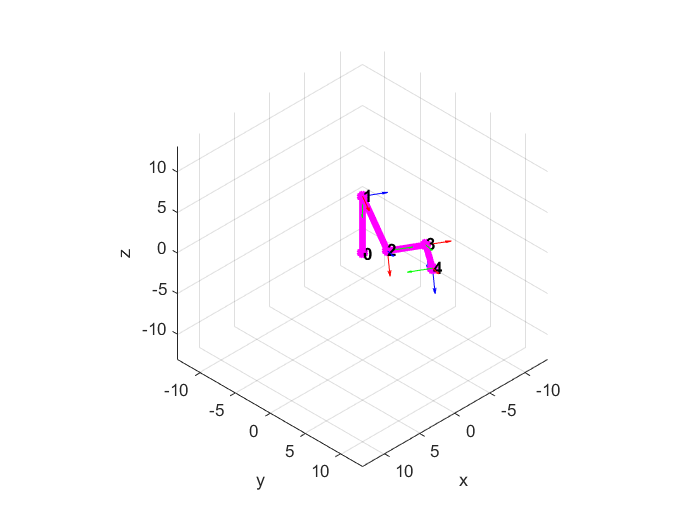

    frame = getframe(gcf);
    writeVideo(videoObj, frame);
end

## **Gráficas**

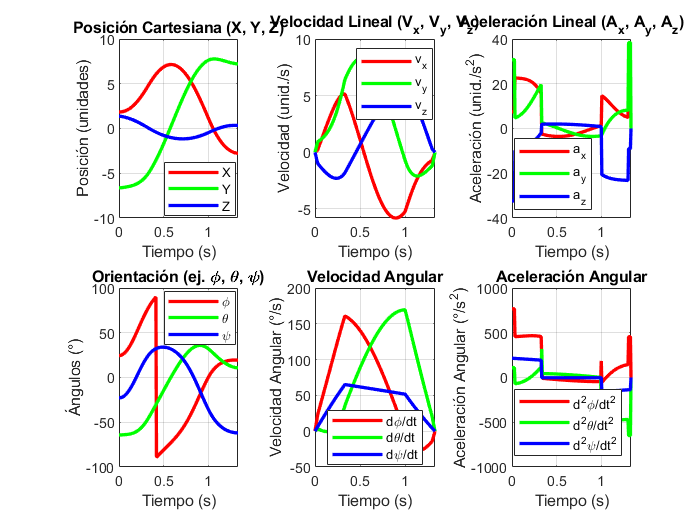

plotCartesian(t, posicion, vel_linear, acel_linear, orientacion, vel_angular, acel_angular)

**Cinemática articular**

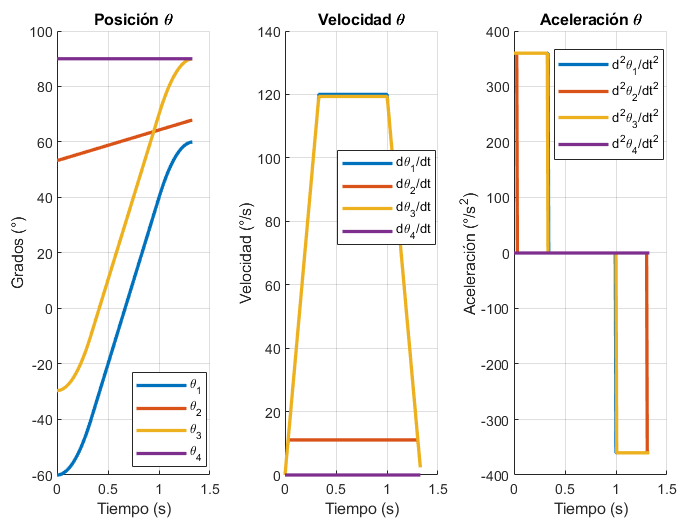

plotJoints(robot,t,q,dq,ddq)